%% Lab 3+4: Final Simulation with Preamble Synchronization
% This script demonstrates a complete digital communication link (Tx -> Channel -> Rx).
%
% Key Features:
% 1. Frame Construction: Uses a Robust Barker Preamble + Random Payload.
% 2. Physics-based Channel: Correctly handles Process Gain for accurate SNR.
% 3. Blind Synchronization: The Receiver uses ONLY the Preamble to find the frame start.
% 4. Visualization: Plots constellations, eye diagrams, and signal traces.

clear; close all; clc;

% Load pre-designed Filter Coefficients (Num, Den)
% Ensure 'my_filter_coeffs_FIR.mat' exists in the current folder.
if isfile('my_filter_coeffs_FIR.mat')
    load('my_filter_coeffs_FIR.mat');
else
    warning('Filter coefficients file not found. Defaulting to internal generation.');
end

%% 1. System Configuration
M = 4;                  % Modulation Order (4-ASK)
Rs = 3.84e6;            % Symbol Rate (3.84 MBaud)
Ns = 64;                % Samples per symbol (Baseband Oversampling)
Vd = 1.0;               % Voltage Distance between constellation points

% --- Sample Rate Configuration ---
% Fs_analog represents the high-speed DAC/ADC sampling rate.
% It must satisfy Nyquist for the carrier frequency: Fs > 2*fc
fc = 1920e6;            % Carrier Frequency (1.92 GHz)
Fs_analog = 4500e6;     % Analog Sample Rate (4.5 GHz)

fprintf('System Configuration:\n');

System Configuration:


fprintf('  Symbol Rate : %.2f MHz\n', Rs/1e6);

  Symbol Rate : 3.84 MHz


fprintf('  Analog Rate : %.2f MHz\n', Fs_analog/1e6);

  Analog Rate : 4500.00 MHz


fprintf('  Carrier Freq: %.2f MHz\n', fc/1e6);

  Carrier Freq: 1920.00 MHz



%% 2. Frame Generation (Preamble + Payload)

% --- A. Design Robust Preamble (Barker Code) ---
% Barker-13 Code is optimal for synchronization due to its low autocorrelation sidelobes.
barker13 = [1 1 1 1 1 -1 -1 1 1 -1 1 -1 1];

% Repetition Strategy:
% Repeating the sequence 4 times significantly increases the correlation energy,
% allowing for successful synchronization even in harsh noise environments.
seq_binary = [barker13, barker13, barker13, barker13]; 

% --- B. Map Preamble to Energy Extremes ---
% To maximize detectability, map the preamble bits to the outermost constellation points.
% For M=4 (Levels: 0, 1, 2, 3):
%   Binary  1 -> Level 3 (Max Voltage)
%   Binary -1 -> Level 0 (Min Voltage)

preamble = zeros(1, length(seq_binary));
preamble(seq_binary == 1)  = M - 1; 
preamble(seq_binary == -1) = 0;     

preamble_len = length(preamble);

% --- C. Generate Random Payload ---
payload_len = 100000;
payload = randi([0 M-1], 1, payload_len);

% --- D. Assemble the Transmit Frame ---
tx_frame = [preamble, payload];

fprintf('Frame Constructed: Preamble (%d syms) + Payload (%d syms)\n', ...
        preamble_len, payload_len);

Frame Constructed: Preamble (52 syms) + Payload (100000 syms)



%% 3. Transmitter Processing
disp('--- Transmitter ---');

--- Transmitter ---


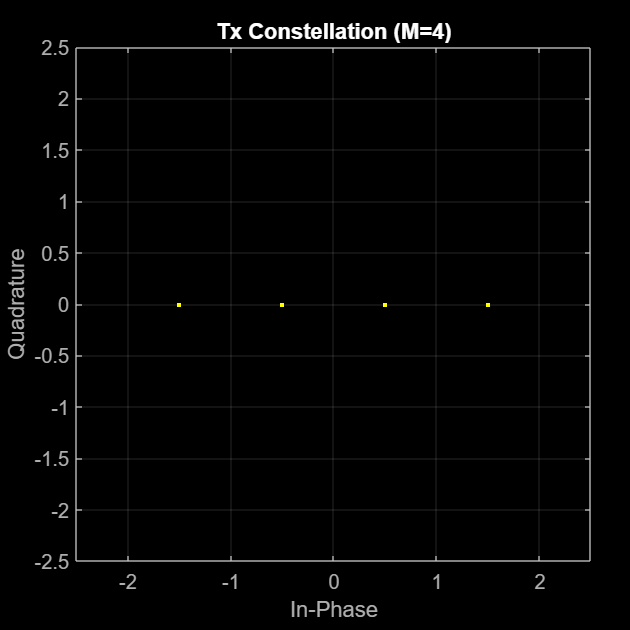


% Initialize Transmitter (Note: Fixed typo 'RCC' -> 'RRC')
tx = Transmitter(M, Rs, fc, Vd, 'RRC'); 

% Manually inject the constructed frame
tx.symbols = tx_frame; 

% Execution Chain
tx.do_mapping();
tx.do_upsampling(Ns);
tx.do_pulse_shaping();
tx.do_dac(Fs_analog);
tx.do_modulation();

% Extract signals for plotting/channel
s_t = tx.modulation.signal;
t_axis = tx.modulation.time;

% Visualization
tx.plot_constellation();

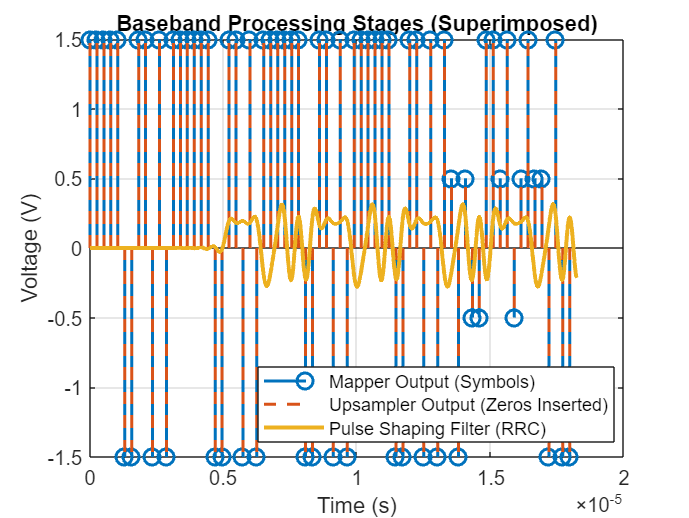

tx.plot_baseband_signals(70); 

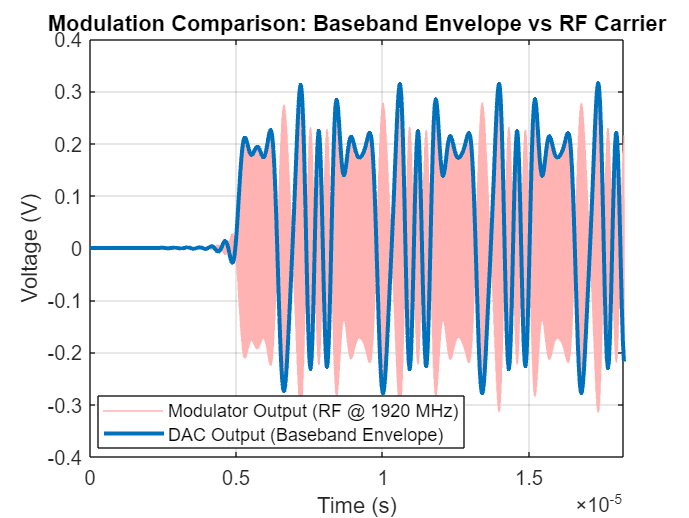

view_time = 70 * (1/Rs); 
tx.plot_modulator_output(view_time);


%% 4. Channel Simulation (AWGN)
disp('--- Channel ---');

--- Channel ---



% --- SNR Calibration ---
% Ideally, we want 'target_snr_db' to be the Es/N0 (Energy per Symbol / Noise Density).
% However, 'awgn' adds noise across the entire Fs_analog bandwidth.
% The receiver filter removes noise outside the signal bandwidth (approx Rs).
% We must subtract this "Processing Gain" from the input SNR to get accurate physics.

target_snr_db = 10; % Desired Es/N0

OversamplingFactor = Fs_analog / tx.Rs;
process_gain = 10 * log10(OversamplingFactor);
input_snr = target_snr_db - process_gain;

fprintf('Adding AWGN: Target SNR = %d dB (Input SNR to AWGN = %.2f dB)\n', ...
        target_snr_db, input_snr);

Adding AWGN: Target SNR = 10 dB (Input SNR to AWGN = -20.69 dB)



r_t = awgn(s_t, input_snr, 'measured');

%% 5. Receiver Processing
disp('--- Receiver ---');

--- Receiver ---



% --- Filter Loading Logic ---
% Attempts to load coefficients (Num/Den) from the workspace.
if exist('Num', 'var') 
    b_coeff = Num;
    if exist('Den', 'var')
        disp('  -> Configured IIR Filter.');
        a_coeff = Den;
        rx = Receiver(M, Rs, fc, Vd, Ns, b_coeff, a_coeff);     
    else
        disp('  -> Configured FIR Filter.');
        rx = Receiver(M, Rs, fc, Vd, Ns, b_coeff);
    end
else
    warning('No filter coefficients found (Num). Generating simple default FIR.');
    fir_lp = designfilt('lowpassfir', 'PassbandFrequency', Rs, ...
        'StopbandFrequency', Rs*2, 'SampleRate', Fs_analog);
    rx = Receiver(M, Rs, fc, Vd, Ns, fir_lp.Coefficients);
end

  -> Configured FIR Filter.


Receiver: Configured for FIR Filter (a=1).



% Execution Chain
rx.do_demodulation(r_t, t_axis);
rx.do_lowpass_filter();
rx.do_downsampling(t_axis);
rx.do_matched_filtering();

disp('  -> Performing Detection (Sampling & Quantization)...');

  -> Performing Detection (Sampling & Quantization)...


rx.do_detection();

%% 6. Preamble Synchronization & Evaluation
disp('--- Synchronization & Results ---');

--- Synchronization & Results ---



% Retrieve all detected symbols (Preamble + Payload + Delays)
rx_seq = rx.detection.symbols; % Note: Using new struct structure .detection.symbols

% --- A. Frame Synchronization ---
% Strategy: Cross-correlate the known Preamble with the received stream.
% The peak location indicates the start of the frame.
delay_start = finddelay(preamble, rx_seq);

fprintf('Preamble detected at index: %d\n', delay_start);

Preamble detected at index: 40


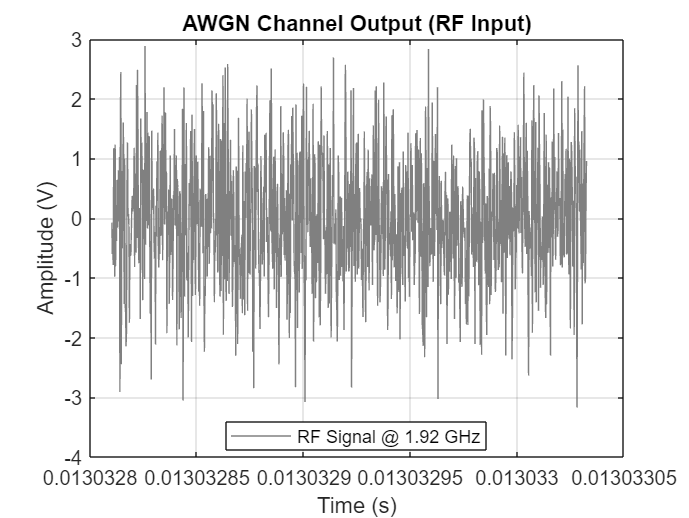

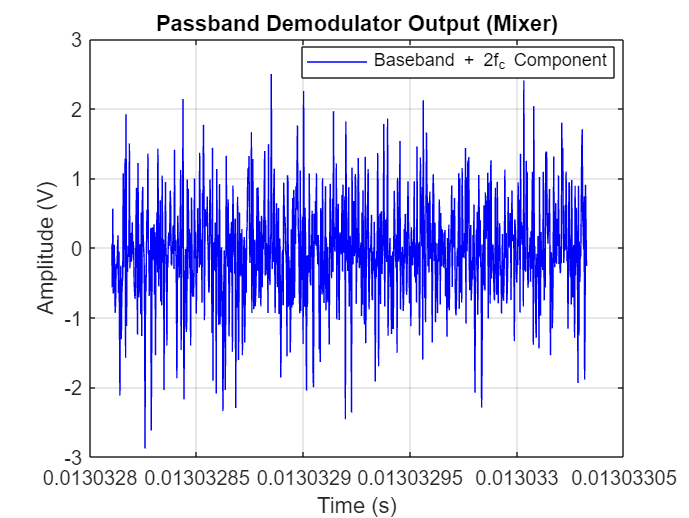

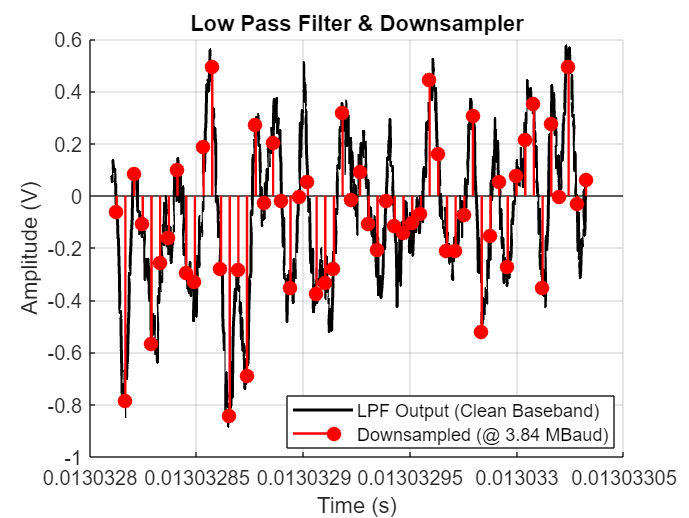

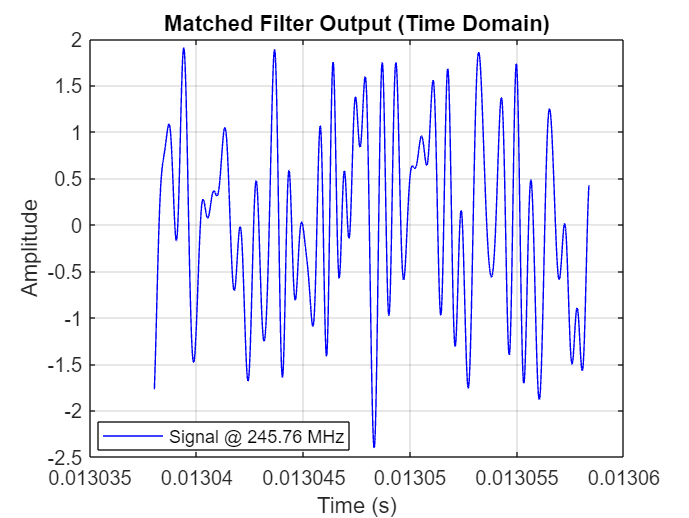

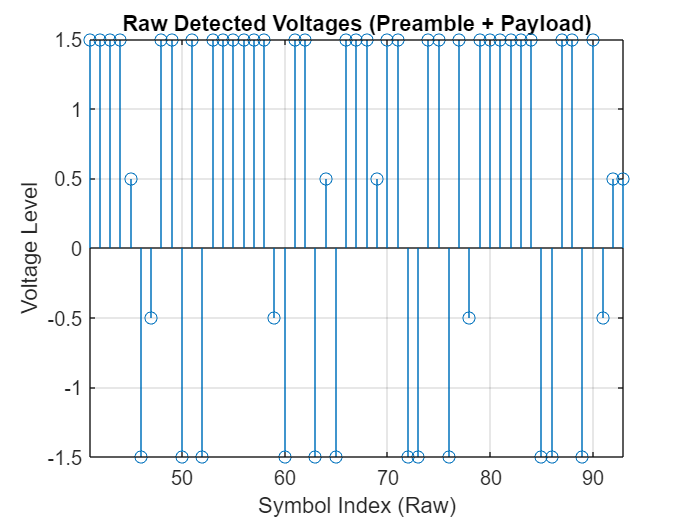

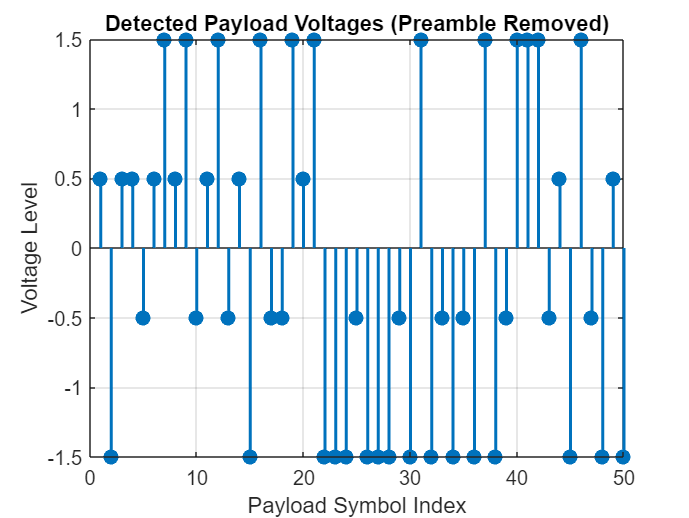

Symbol Error Rate (SER): 0.12307 (12307 errors / 100000 symbols)


RESULT: Transmission complete with errors.



Data Integrity Check (First 15 symbols):


  Tx: [2 0 2 1 1 3 3 2 3 1 2 3 2 2 0]


  Rx: [2 0 2 2 1 2 3 2 3 1 2 3 1 2 0]



if delay_start >= 0
    % --- B. Payload Extraction ---
    % Logic:
    % Frame Start = delay_start + 1 (because finddelay returns lag)
    % Payload Start = Frame Start + Preamble Length
    
    idx_payload_start = delay_start + preamble_len + 1;
    idx_payload_end   = idx_payload_start + payload_len - 1;
    
    % --- Visualization of Receiver Internals ---
    % 1. View Raw RF Input (needs r_t and t_axis from Channel)
    rx.plot_channel_output(r_t, t_axis);
    % 2. View Mixer Output (High Freq + Baseband)
    rx.plot_mixer_output();
    % 3. View Final Baseband (LPF + Downsampling)
    rx.plot_lpf_and_downsampler();
    % 4. Matched Filter Waveform
    rx.plot_matched_filter_output();      
    % 5. Raw Voltages (Including Preamble)
    rx.plot_raw_detected_voltages(preamble_len);      
    % 6. Aligned Payload (Valid Data Only)
    rx.plot_aligned_payload(idx_payload_start); 
    
    % --- C. Bounds Checking & Error Calculation ---
    if idx_payload_end <= length(rx_seq)
        
        % Extract the relevant payload segment
        rx_payload = rx_seq(idx_payload_start : idx_payload_end);
        
        % Calculate Bit/Symbol Errors
        errors = sum(payload ~= rx_payload);
        SER = errors / length(payload);
        
        fprintf('Symbol Error Rate (SER): %.5f (%d errors / %d symbols)\n', ...
            SER, errors, length(payload));
        
        if SER == 0
            disp('SUCCESS: Preamble Sync & Data Recovery successful.');
        else
            disp('RESULT: Transmission complete with errors.');
        end
        
        % Visual Verification (First 15 symbols)
        fprintf('\nData Integrity Check (First 15 symbols):\n');
        fprintf('  Tx: %s\n', mat2str(payload(1:15)));
        fprintf('  Rx: %s\n', mat2str(rx_payload(1:15)));
        
    else
        disp('Error: Frame end not received (Delay too large or simulation too short).');
    end
else
    disp('Error: Synchronization Failed (Preamble not found). Check SNR or Filters.');
end

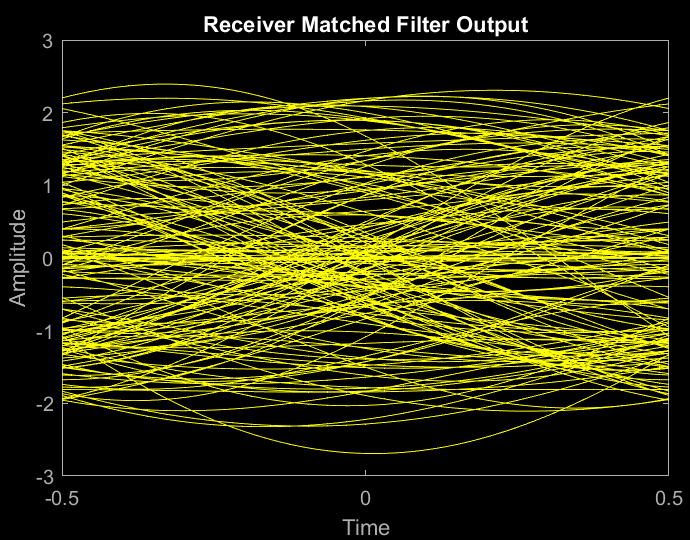


%% 7. Eye Diagram Analysis
% Plot the eye diagram of the matched filter output to check for ISI.
% Note: We use .signal from the struct and access Ns via the object.
figure('Name', 'Receiver Eye Diagram');
% Take a slice from the middle to avoid transient edges
safe_start = 100;
safe_end = min(12000, length(rx.matched.signal));
eyediagram(rx.matched.signal(safe_start:safe_end), rx.Ns);
title('Receiver Matched Filter Output');